clear;close all;
make_ieee_figures();

## Plot Configuration

path_to_processed_results = "/simresults/sim/USER/sg-flooding/XX_sim-results_processed";
path_to_export_figures = "/home/USER/TUHH/Publications/USER-sg-flooding/paper/IMG/";
export_figures = true;
global confidenceLevel;
global publicationColors;
global numRuns;
numRuns = 5;
confidenceLevel = 95;
publicationColors = [0  , 45, 106;
                     227, 27, 35 ;
                     0  , 92, 171;]./255;

## Plot Selection

% Plot 1: Matrix Plot for Topology A
plot_1 = false;
aoi_matrix_experiment_name = "fixedThresholdMatrix";

% Plot 2: Compare Static vs Dynamic RTX Timer for Topology A
plot_2 = false;
aoi_over_seq_experiment_names_static_vs_dynamic = ["dynamicLow";"fixedThresholdMatrix"];

% Plot 3: Compare Low vs High Datarate Medium for Topology A
plot_3 = false;
aoi_over_seq_experiment_names_topo_a = ["dynamicLow";"dynamicHigh"];

% Plot 4: Compare Low vs High Datarate Medium for Topology B
plot_4 = false;
aoi_over_seq_experiment_names_topo_b = ["dynamicLargeLow";"dynamicLargeHigh"];

% Plot 5: Compare Low vs High Datarate Medium for Topology A but for Peak AoI
plot_5 = false;
peak_aoi_over_seq_experiment_names =  ["dynamicLow";"dynamicHigh"];

% Plot 6: Topology Plots
plot_6 = false;

% Plot 7: Bar Graphs
plot_7 = false;
bar_graph_experiment_names =  ["dynamicLow";"dynamicHigh";"dynamicLargeLow";"dynamicLargeHigh"];

 

if(plot_1)
    f1_aoi_matrix_color;
end

if(plot_2)
    aoi_over_seq_experiment_names = aoi_over_seq_experiment_names_static_vs_dynamic;
    legendNames = [{["Dynamic RTX (R=5)"]},{["Static RTX (R=1)"]}];
    savename = "best_aoi_over_seq";
    f2_best_aoi_over_seq;
end

if(plot_3)
    aoi_over_seq_experiment_names = aoi_over_seq_experiment_names_topo_a;
    legendNames = [{["2 Mbit/s (R=5)"]},{["11 Mbit/s A (R=5)"]}];
    savename = "best_aoi_over_seq_top_a";
    f2_best_aoi_over_seq;
end

if(plot_4)
    aoi_over_seq_experiment_names = aoi_over_seq_experiment_names_topo_b;
    legendNames = [{["2 Mbit/s (R=1-2)"]},{["11 Mbit/s A (R=1-2)"]}];
    savename = "best_aoi_over_seq_top_b";
    f2_best_aoi_over_seq;
end

if(plot_5)
    legendNames = [{["2 Mbit/s (R=5)"]},{["11 Mbit/s (R=5)"]}];
    f3_max_peak_aoi_over_seq;
end

### INFO: Best optimal number of streams for: dynamicThreshold is at k = 6
### INFO: Best optimal number of streams for: dynamicThresholdHigh is at k = 10


### INFO: Best optimal number of streams for: dynamicLargeLow is at k = 6
### INFO: Best optimal number of streams for: dynamicLargeHighDR is at k = 7


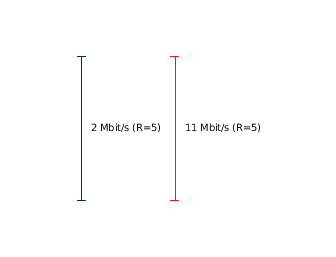

if(plot_6)
    f6_topology;
end


if(plot_7)
    legendNames = [{["2 Mbit/s (R=5)"]},{["11 Mbit/s (R=5)"]}];
    f7_bar_graphs;
end